# ENGR105    ---    Problem Set 9    ---   Audio processing

## Due: Friday, 11/6/2020

## Name:

#### The University of Pennsylvania code of academic integrity can be found here:

[https://catalog.upenn.edu/pennbook/code-of-academic-integrity/](https://catalog.upenn.edu/pennbook/code-of-academic-integrity/)

By submitting this assignment, you certify that you completed this assignment in compliance with the code of academic integrity, as defined above, and that the work here is your own. Collaboration is allowed and encouraged but  it is in your own best interest to be able to complete all the problems on your own. Collaboration is allowed, COPYING is NOT. Be sure you are able to reason through each step. 

#### Notes on HW submission:

- Please save the final document In the following format: "<your last name>_<your first name>_HW9.mlx

- Run the entire document (`f5`) prior to submitting. Following this, please **export to .pdf** and **submit both** the .mlx file and the .pdf file to Canvas.

- The LiveScript file may be exported to PDF using the **Save** dropdown menu. **Please also see my recent email regarding alternative methods for exporting to PDF.**

- If it is not selected by default, select "Output Inline" at the top right of the LiveScript document to display the output below your code (rather than to the right).

#### Purpose of this problem set:

- Gain familiarity importing, analyzing, and processing audio files and text.

- Have fun creating songs and audio.

#### Notes about MATLAB LiveScripts:

- The gray regions are "code" regions. Entering and running your code here is the same as running it in a `.m` script file or on the command line.

- "Running a piece of code" means you are executing the code in that section only. **Press **`Cntl`** + **`Enter`** to run a given section.**

- Press `f5` to run all sections of the document.

- To remove inline figures, right click and select "Clear All Output."

- When you run a section (each section refers to a different problem or part of a problem), all variables and vectors are stored in MATLAB and may be called from the command line.

**Reminder: Prior to submitting, be sure to run ****all**** sections of the document to ensure that it works properly. After running all sections, export the document to pdf.**

## PROBLEM 1 (50 pts): Processing audio in MATLAB

**Note****: For all parts of this homework, please do ****not**** use any functions or other capabilities provided in any toolboxes. Only use the functions contained in the base MATLAB package.**

Audio signals, sound, and music are important in engineering and also prevalent all around us in everyday life. Sound propagates through a medium (*e.g.* air) as a longitudinal wave: at its source, vibrations in the source material (*e.g. *a drum, vocal chords, car horn in Philadelphia) generate local compressions and expansions in the air that can propagate outward. We hear sound when these vibrations reach our ear canals and cause our eardrums to vibrate. [Through a cascade of biological and neurological processes](https://www.nidcd.nih.gov/health/how-do-we-hear), our brains transform these eardrum vibrations into our perception of sound.

Sound can be *sampled* at a specific frequency (**typically 44.1 kHz**) and stored or represented as an *audio signal*. In MATLAB, audio signals are vectors of class `double`, whose entries can vary between `-1` and `1`. The entries in an audio signal are sometimes referred to as a representation of *acoustic pressure*, and can be **converted into a voltage that applied to an electric component in your speaker**. The varying voltage applied to a speaker will cause it to produce vibrations in the air accordingly, and your audio signal can be *heard* by those nearby. In this homework, we will analyze and create audio signals.

**a)** Consider an important audio signal in biomedical engineering: a heart beat. This can be found in `clip0.mp4`. Load the **audio signal** and the **sampling frequency** (using `audioread)`, listen to it using the `sound()` function, and plot the signal over time. For all parts in this problem that requiring plotting, the x axis should be in units of **seconds**.

[heart_signal, Fs] =  audioread('clip0.mp4');
disp(Fs)

       44100



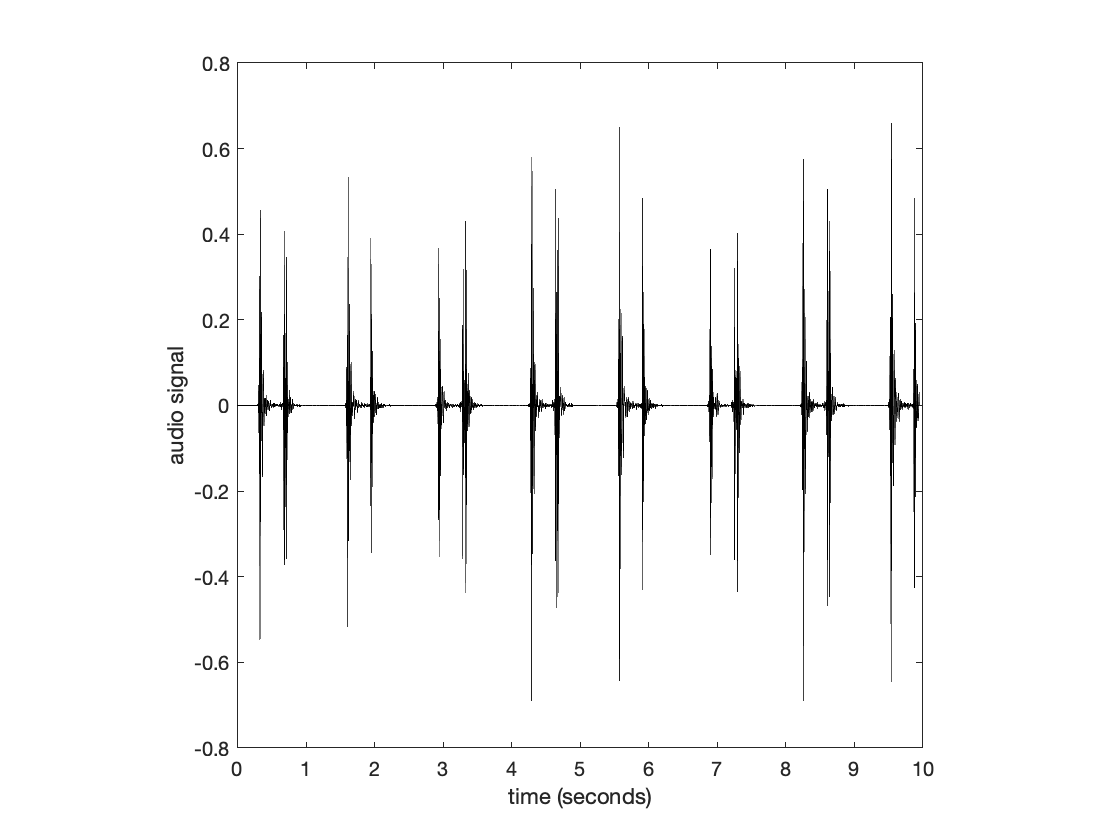

sound(heart_signal, Fs)
time = 1/Fs*(1:size(heart_signal, 1));
plot(time, heart_signal,'k')
xlabel('time (seconds)')
ylabel('audio signal')
axis square

Your plot should look similar to the following (without the orange box). The orange box denotes *one beat *of the heart as blood is pumped through the heart's chambers.

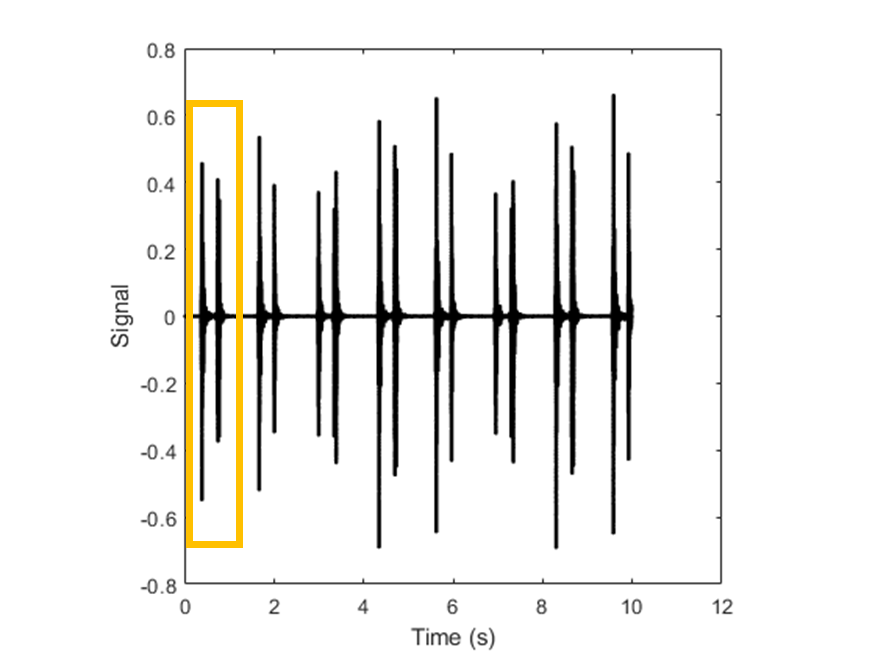

**b)** As seen above, a sound that is read into MATLAB is simply a numerical array of type double. Note that values in this array can vary from -1 to 1. Realizing that the imported audio signal is *just* numerical data over time,** create a MATLAB script** to estimate the **beats per minute** (**bpm**) of the heartbeat analyzed above. **Please display the bpm determined from your code**. Ensure that all of your steps are clearly commented.

time = 1/Fs*(1:size(heart_signal, 1));


%filter out if the numbers are greater than a certain amount 

% Create a rolling mean filter
windowSize = 1000;
b = ones(1,windowSize);
a = windowSize;




t = time/Fs;

maxfiltered = heart_signal(:,1);
%run through the entirety of the heart signal 
for k = a+1:length(heart_signal) - a
    index = k-a: k+a;
    maxfiltered(k) = max(abs(heart_signal(index)));
end

Above_threshold = time(maxfiltered>0.45);
%use thresholds for 2 different peaks
threshold_1 = Above_threshold(Above_threshold<1);
threshold_2 = Above_threshold(Above_threshold>1.5 & Above_threshold<1.7);
%take the difference of the peaks
time_difference = threshold_2(1) - threshold_1(1);
%find the bpm
bpm = 60/time_difference

bpm = 46.8169


% % Plot audio signal
% plot(time,y_signal,'k-')
% hold on
% plot(time,y_filtered,'r-','LineWidth',2)
% hold off
% axis square
% xlabel('time (s)')
% ylabel('audio signal')
% xlim([0,1])

**Notes and tips: **

- Potentially helpful operations include using the absolute value function, logical indexing, smoothing or filtering the signal.

- Plotting is not required for this problem. However, even if you don't show any plots, plotting the signal (or mathematical operations you perform on it) over time could be helpful.

According to the Mayo Clinic, a** normal** resting **heart rate** for adults ranges from **60 to 100** beats per minute, though a young, healthy **athlete** may have a **heart rate** of **30 to 40** bpm.

**c)** **Load the rest of the audio clips** (there should be 7 more) into a structure array called `p1_C`. Listen to each of these clips, as above. **Create a single visualization (plot) that accurately and concisely represents each signal**. As above, ensure that the x axis for all signals is in units of seconds and that your visualization looks professional.

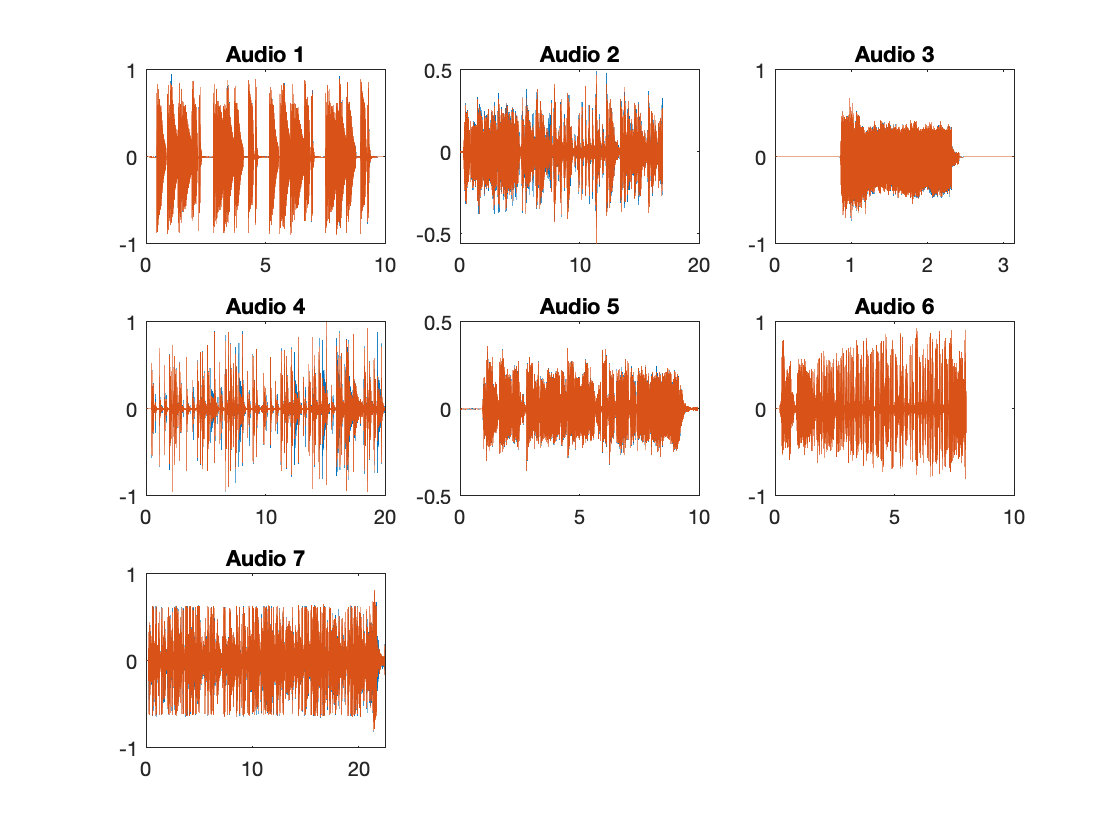

p1_C = struct;

%create a structure array with a loop

for k = 1:7
    [p1_C(k).audio, p1_C(k).Fs] = audioread(['clip',num2str(k), '.mp4']);
end

for k =1:7
    sound(p1_C(k).audio, p1_C(k).Fs)
end

%create a time vector
close all
for k = 1:7
    t = (1:size(p1_C(k).audio,1)) / p1_C(k).Fs;
    title(['Audio ', num2str(k-1)])
    subplot(3,3,k)
    plot(t,p1_C(k).audio)
end
subplot(3,3,7)
title('Audio 7')

**d)** Since the imported audio clips in **c)** are **just vectors of numerical information, these can be combined, modified, concatenate**d, etc in the same way that we would for other array operations. **Listen to the following example** that is created only by combining arrays. **Note**: you will need to ensure the naming convention in this example matches that of your structure array created in **c)**, so feel free to make any necessary changes to the field names in the following example.

**Example mix from DJ Mike**

% Note: I stored all of my clips in the structure array in part C.
% p1_C(1).audio -> corresponds to audio array from clip 1
% p1_C(2).audio -> corresponds to audio array from clip 2
% p1_C(3).audio -> corresponds to audio array from clip 3
% p1_C(1).Fs -> corresponds to the sampling frequency from clip 1
% p1_C(2).Fs -> corresponds to the sampling frequency from clip 2
% p1_C(3).Fs -> corresponds to the sampling frequency from clip 3

% 1) From clip2.mp4
% Specify that we only want to stop at the index position corresponding to 10 seconds
te2 = round(10.0*p1_C(2).Fs);
% Create a subarray corresponding to first 10 seconds
c2 = p1_C(2).audio(1:te2,:);


% 2) From clip1.mp4
% Specify that we want to take the first five seconds, and start it AFTER
% five seconds
% index corresponding to 5 seconds
te1 = round(5.0*p1_C(1).Fs);

% Create a subarray corresponding to the first five seconds of clip 1
c1 = p1_C(1).audio(1:te1,:);

% Create a zeros vector of same length as c1. That is, this vector will be used to
% "delay" the start of clip c1 by five seconds
initially_zero = zeros(size(c1)); 
c1 = [initially_zero;c1];


% 3) From clip3.mp4
% Time offset
tc = 3.2;   

% Create a vector that is the same size as c1 (and therefore c2).
c3 = zeros(size(c1));

% Start audio from clip3 at 3.2 seconds in
c3(p1_C(3).Fs*tc+1:p1_C(3).Fs*tc+size(p1_C(3).audio,1),:) = p1_C(3).audio;


% 4) Add all clips together. I multiply c1 by 1.5 to effectively "bass
% boost" the output
mashup = 1.5*c1 + c2 + c3;
% Scale so that the max absolute value is less than or equal to 1
mashup = mashup/max(abs(mashup));
mashupFs = 44100;


% Play the mashup 
%sound(mashup,mashupFs)

Create your own mix of the audio signals and play it using the `sound()` command. You can create a mix however you want -- just ensure that you use **at least ****two**** of the above clips** (`clip0 ... clip7`) and that your composite audio mix is **at least ****5 seconds** long.

**Notes:**

- Since the audio vectors are different sizes, you will need to pay very close attention to **array indexing**.

- All of the above clips should have the same sampling frequency.

- **Audio vectors must be scaled to be within the interval [-1,1] **or the sound produced using the `sound()` function will be distorted. Include a scaling operation at the end of your code (as above) to ensure your sound vector is within the bounds.

%utilize audio file 4 because its a drum beat
a4 = p1_C(4).audio;

%start somewhere in the audio file 
a4start = round(5*p1_C(5).Fs);
a4_sound = p1_C(4).audio(a4start:end,:);

%make vector of zeros to fill in space
a4_silence = zeros(a4start,2);

%concatenate the sounds 
a4 = [a4_silence;a4_sound];

%use audio five and take the beginning of it. 
a5stop = round(5*p1_C(5).Fs);
a5_sound = p1_C(5).audio(1:a5stop,:);

%create silence vector to add onto audio 4 
a5_silence = zeros(length(a4)-length(a5_sound),2);
a5 = [a5_sound;a5_silence];

%concatenate the two sounds 
mashup = a4 + a5;
mashup = mashup/max(abs(mashup));
mashupFs = 44100;
sound(mashup, mashupFs)


## Problem 2 (50 pts): creating audio in MATLAB

As mentioned above, sound is generated by vibrations (i.e. periodic oscilations) of some material, such as the membrane of a drum, the string on a guitar, or the (voltage-dependent) oscillations of electromechanical components in your computer or headphone speakers. We can engineer an audio signal to be of a certain pitch by creating a signal that oscillates with some frequency:

            
$$g\left(t\right)=\sin \left(2\pi \;f\;t\right)$$


In the above equation, $g\left(t\right)$ will oscillate between -1 and 1 at a frequency $f$. *Vibrations that occur with a higher frequency correspond to a higher pitch*. 

**a)** Create a script that plays a **middle C** for **one second**. This note corresponds to a frequency of **261.63 Hz**. Use the `sound()` function to listen to it.

f = 261.63;
t = 0:0.1:1;
gt = sin(2*pi*f*t);
plot(t,gt)
axis square
sound()

**Notes**: 

- Use a sampling frequency of 44.1 kHz for this problem, as in the above cases.

- The **musical** frequency is different from the **sampling** frequency. The musical frequency defines the pitch of a sound, the sampling frequency describes how well a discrete signal represents a continuous signal.

- The sampling frequency specifies the number of points in the audio signal per second.

**b)** The text file (`MusicalFrequency.txt`) contains a list of names and the associated frequencies for different musical notes. Import this data as a structure array named `musicInfo`.

musicInfo = importdata("MusicalFrequency.txt");

**c)** Create a function called `playNote`, and store it at the end of this LiveScript file. This function should have the following characteristics:

- It should take** three inputs**: a character array corresponding to the note to be played, the duration of the audio signal, and the structure array (`musicInfo)` containing the note names and frequencies (created in **b)**).

- It should produce **one output**: a vector containing the audio signal produced at the input frequency for the specified duration.

- Eventually, we will want to combine multiple notes into a piece of music. Because of this, you may want to build in separatation between notes by having a given note *stop* before the end of the specified duration. For example, when you specify a note to be "played" for 1 second, 80% of that time could be the note and the last 20% of the time could be silence (corresponding to array elements that are zero). 

- As always, ensure that your code is clear and well-commented.

Uncomment the following call -- this should call your function to play an "**G**" for two seconds.

 y_C = playNote('G4',2,musicInfo);
 sound(y_C,44100)


**d)** Using your function, create a **C major** chord that plays for 1 second. That is, the created audio signal should contain the notes '**C4**', '**E4**', and '**G4**' being played at the same time.

**Notes:**

- As above, all audio signals (vectors) should be scaled so that all vector elements are less than 1 and greater than -1.

- Your function `playNote` should not be modified for this rest of homework problem 2.

C4 = playNote('C4', 1, musicInfo);
E4 = playNote('E4', 1, musicInfo);
G4 = playNote('G4', 1, musicInfo);
C_major = C4 + E4 + G4;
C_major = C_major/max(abs(C_major));
sound(C_major, 44100)

**e)** In the above case, we created music in terms of "seconds," though we would prefer to specify how notes are played in terms of "beats." If we do that, we can change the tempo of our song simply by modifying the `bpm` (beats per minute) of our song rather than directly changing our inputs into `playNotes`.

Create a script that does the following:

- Establishes a variable `bpm` that specifies the beats per minute of our audio.

- Set `bpm` to a value of 120.

- Copy and paste your chord from **d)** to the script here, but specify that the **the chord plays for one beat**.

- **The chord should play for one beat regardless of the value of the variable **`bpm`. Try a few different values of `bpm` (while ensuring the chord still plays for one beat) to see how the **duration** of the chord changes.

bpm = 120;
duration = 1;

t = @(beat) beat/bpm*60;

C4 = playNote('C4', duration, musicInfo);
E4 = playNote('E4', duration, musicInfo);
G4 = playNote('G4', duration, musicInfo);

C_major_chord = (C4 + E4 + G4)/3;
sound(C_major_chord,Fs)


**Hints: **

- Converting from "beat duration" to "time duration" is just a **unit conversion** based on the `bpm` value we specify in our script.

- One way to carry out this conversion could be to create an anonymous function that takes an input in "beats" and produces an output in "seconds." 

**f)** Building upon what you have created in **e)**, **create a script that is capable of "reading" a piece of music** from a text file. **Use it to "play" the scale in **`p2_F.txt`, according to the following information.

**Details of **`p2_F.txt`**:**

- In a given row, the first entry represents a note to be played.

- In a given row, the second entry specifies the **number of beats** that this note should be played for.

- In a given row, the third column specifies the "**musical index**" (in terms of beats) at which this note should be added to the composite audio array.

- Only the notes in black are contained within `p2_F.txt`. The grayed-out portions are just to visualize the rest of the scale.

**Visual representation of what should happen when **`p2_F.txt`** is played:**

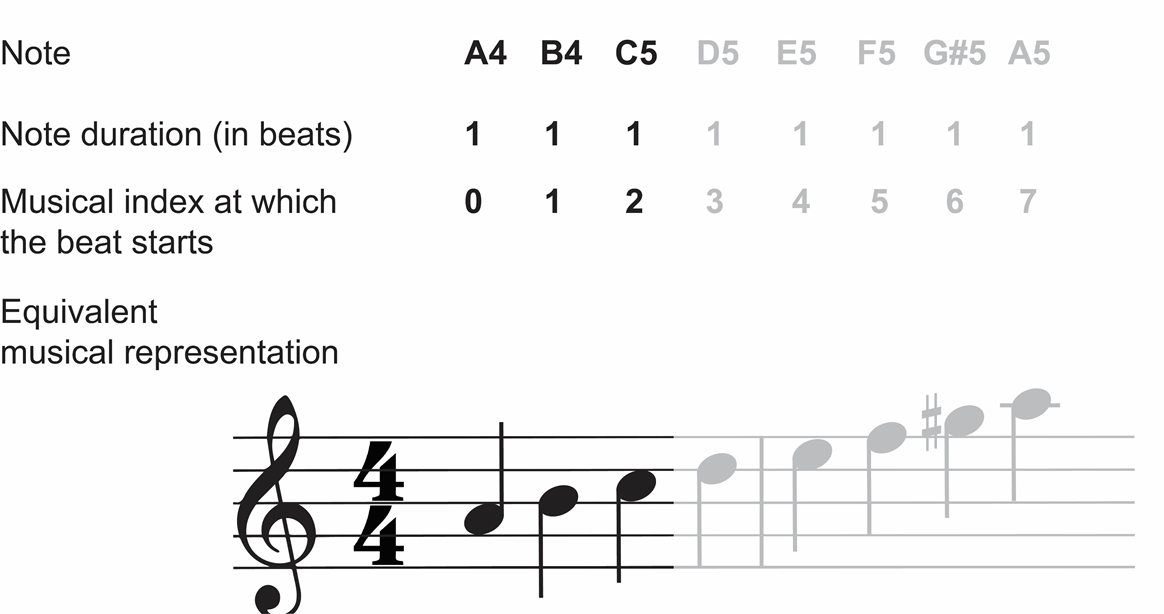

**Written description of what should happen when **`p2_F.txt`** is played:**

Your script should play three notes, one at a time. First, `'A4' `should be played immediately for a duration of one beat (that is, `'A4'` is played on musical index 0 and lasts for one beat). Next, `'B4'` should be played for a duration of one beat (that is, `'B4'` starts on musical index 1 and lasts for one beat). Finally, `'C4' `should be played for a duration of one beat (that is, `'C4'` starts on musical index 2 and lasts for one beat). Thus, the total duration of music is for three beats.

**Hints and more details:**

- At the conclusion of your script, you should have **one array of audio data** containing all three notes that are played.

- **The function **`readcell()`** is a useful way to read a comma-delimitted file directly into a cell array.**

- Use `sound() `frequently to check to make sure your code is working as expected.

- As above, ensure that the elements of your final audio array are between -1 and 1.

%set the bpm
bpm = 120;
%make one beat using the bpm 
onebeat = (1/bpm)*60;
p2_F = readcell('p2_F.txt'); 

A4 = playNote(p2_F(1,1), onebeat, musicInfo);
B4 = playNote(p2_F(2,1), onebeat, musicInfo);
C5 = playNote(p2_F(3,1), onebeat, musicInfo);

scale = [A4,B4,C5];
sound(scale, 44100)










**g)** Your script created in **f)** should also be able to read more complicated files (*e.g.* with notes starting on half or quarter of beats) that are of the same format. Copy/paste your script from **f)**, make any necessary adjustments, and use your code to:

- Convert the `p2_G_treble.txt` and `p2_G_bass.txt` into two audio arrays of the same length.

- Combine these two audio arrays (I recommend `treble_array + 5*bass_array` to boost up the bass).

- Scale the composite audio to be between -1 and 1.

- **Listen** to and **plot** the output audio signal.

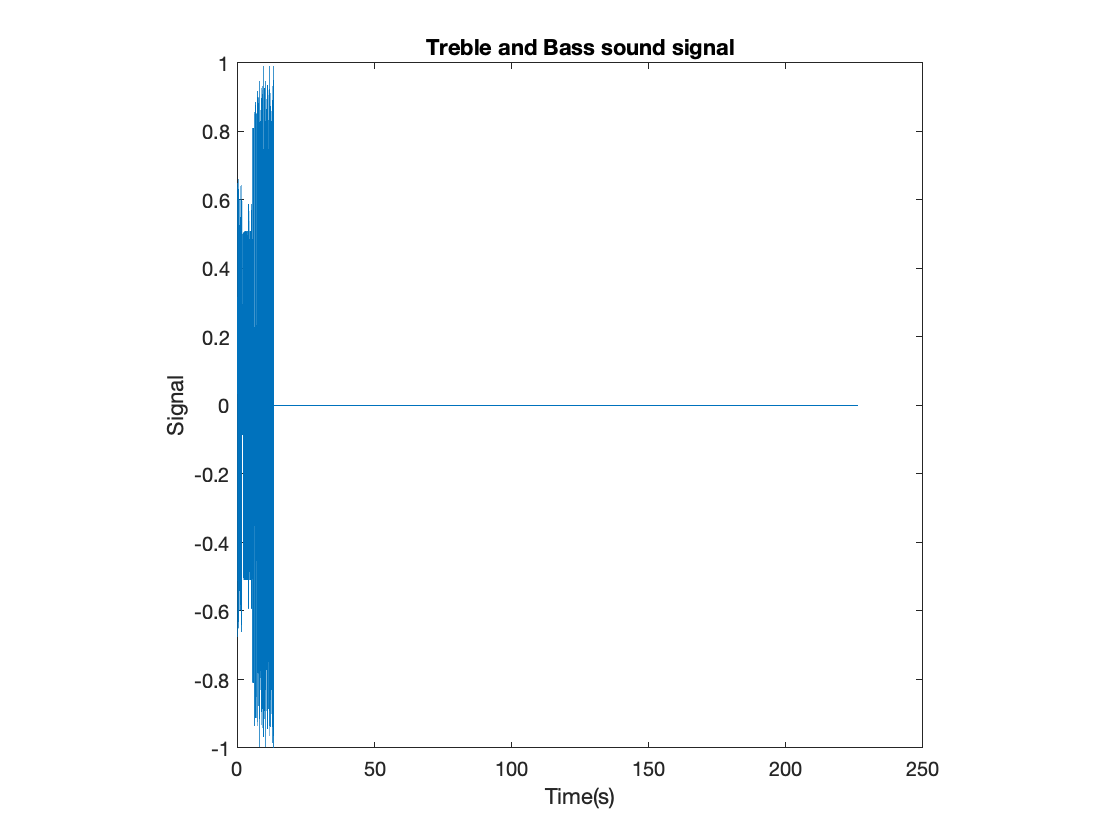

%turn text files into a cell aray
treble_array = readcell('p2_G_treble.txt');
bass_array = readcell('p2_G_bass.txt');

Fs = 44100;
%set bpm to 120
bpm = 120;

%hold the sounds in vectors
treble_sound= zeros(1,10^7);
bass_sound = zeros(1,10^7);

%now need to create a base sound using the treble array
for k = 1:length(treble_array)
    %calculate the length of the notes using the treble array and the
    %amount of seconds it lasts 
    note_length = treble_array{k,2};
    note_length_seconds = note_length*(60/bpm);
    
    currentnote = playNote(treble_array{k,1}, note_length_seconds, musicInfo);
    
    %locate start of time index and place note in vector 
    tstart = round(treble_array{k,3}*44100*(60/bpm))+1;
    tend = round(treble_array{k,3}*44100*(60/bpm))+length(currentnote);
    
    treble_sound(tstart:tend) = treble_sound(tstart:tend) + currentnote;
end

%now do a similar thing with the bass array
for i = 1:length(bass_array)
    note_length = bass_array{i,2};
    note_length_seconds = note_length* (60/bpm);
    
    currentnote = playNote(bass_array{i,1},note_length_seconds, musicInfo);
    
    tstart = round(bass_array{i,3}*44100*(60/bpm)) +1;
    tend = round(bass_array{i,3}*44100*(60/bpm))+length(currentnote);
    
    bass_sound(tstart:tend) = bass_sound(tstart:tend) + currentnote;
end

totalSound = treble_sound + 5*bass_sound;
%normalize so that it is between -1 and 1
normTotalSound = totalSound/max(abs(totalSound));

%output the sound 
sound(normTotalSound, 44100);
time = 1/Fs*(1:length(normTotalSound));

close all
plot(time,normTotalSound)
axis square
title('Treble and Bass sound signal')
xlabel('Time(s)')
ylabel('Signal')

## Problem Set 9: functions stored below

**Use the space below for PROBLEM 2c).**

**c)** Create a function called `playNote`, and store it at the end of this LiveScript file. This function should have the following characteristics:

- It should take** three inputs**: a character array corresponding to the note to be played, the duration of the audio signal, and the structure array (`musicInfo)` containing the note names and frequencies (created in **b)**).

- It should produce **one output**: a vector containing the audio signal produced at the input frequency for the specified duration.

- Eventually, we will want to combine multiple notes into a piece of music. Because of this, you may want to build in separatation between notes by having a given note *stop* before the end of the specified duration. For example, when you specify a note to be "played" for 1 second, 80% of that time could be the note and the last 20% of the time could be silence (corresponding to array elements that are zero). 

- As always, ensure that your code is clear and well-commented.

function signal = playNote(note,duration,musicInfo)
    
    
    
    Fs = 44100;
    %time vectore 
    t =linspace(1/Fs, duration, Fs*duration);
    %set frequency of the notes
    notefrequency = musicInfo.data(strcmp(note, musicInfo.textdata));
    
    signal = (sin(2*pi*(notefrequency*t)));
    %have a break in the sound so that there is 20% silence
    rest = zeros(1,floor(.2*length(signal)));
    %use the 20% silence and the 80% sound to makea  signal
    signal = [signal(1:ceil(.8*length(signal))),rest];

%     t_gap = t(1:(0.8*length(t)));
%     
%     signal(1:(0.8*length(t))) = sin(2*pi*(musicInfo.data(index)).*t_gap);
end










